#### Test file for labeling automation algorithm

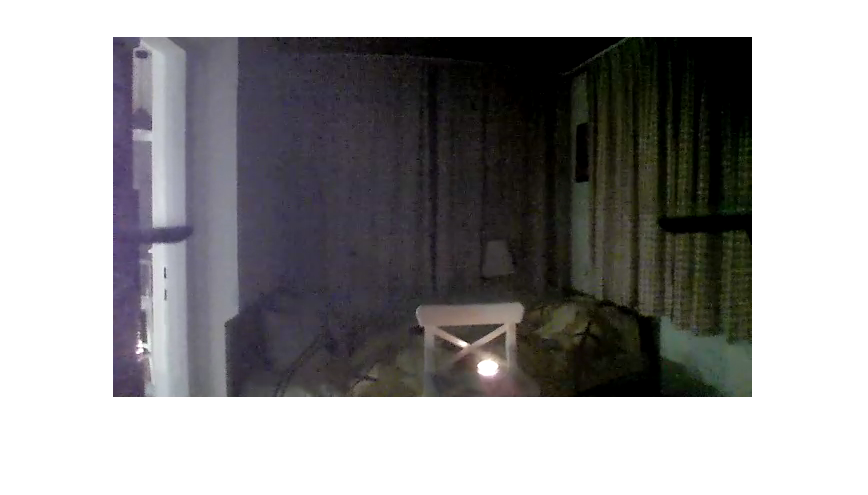

I = imread('testImages\lab1_4.png');

imshow(I)

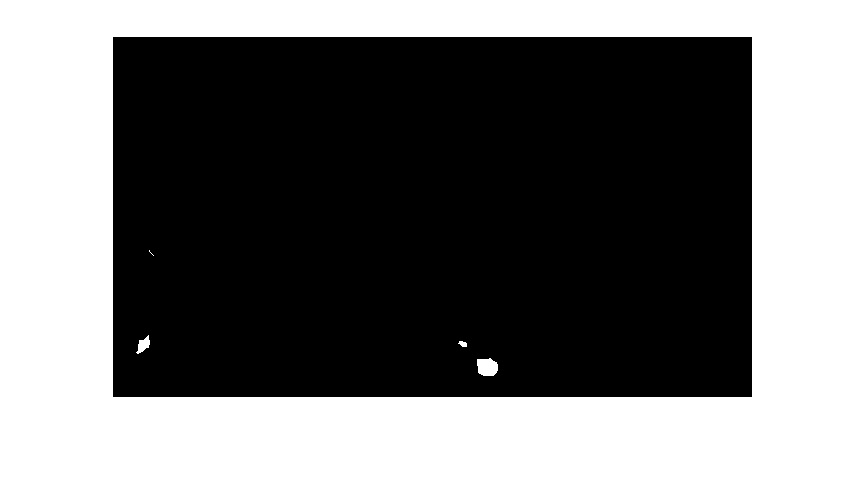

[BW,maskedRGBImage] = extract_red(I);
BW_C = imclose(BW, strel('disk', 15));
BW_f = imfill(BW_C, 'holes');
imshow(BW_f)

s = regionprops(BW_f);
[sortedArray, i] = sort([s.Area], 'descend');
imgSize = size(I);

for idx = 1:i
fireBoundBox = s(idx);
  if  (fireBoundBox.BoundingBox(3) > 10 && fireBoundBox.BoundingBox(4) > 10 && fireBoundBox.BoundingBox(3) < imgSize(2))
      
    f = insertObjectAnnotation(I, 'rectangle',fireBoundBox.BoundingBox, 'fire');
    imshow(f);
  end
    
 
end

parrotObj = parrot();
takeoff(parrotObj);
move(parrotObj, 2.0,'pitch' ,deg2rad(-10),'roll' ,deg2rad(-0.01));
land(parrotObj);

Connection to the Parrot drone timed out. Connect the computer to the drone's WiFi network.

clear parrotObj;

*Copyright 2019 The MathWorks, Inc.*